%% Script de identificación del sistema con parámetros dados

% Parámetros físicos
J_tot = 0.006;   % kg·m^2
r     = 0.16;     % m
M_tot = 0.293;    % kg
b     = 0.00001357;   % fricción viscosa
h     = 0.035;     % m
g     = 9.81;     % m/s^2

% Función de transferencia: G(s) = r / (J_tot*s^2 + b*s - M_tot*g*h)
num = [r];
den = [J_tot, b, -M_tot*g*h];
G = tf(num, den);

disp('Función de transferencia G(s):');

Función de transferencia G(s):


G


G =
 
                0.16
  --------------------------------
  0.006 s^2 + 1.357e-05 s - 0.1006
 
Continuous-time transfer function.


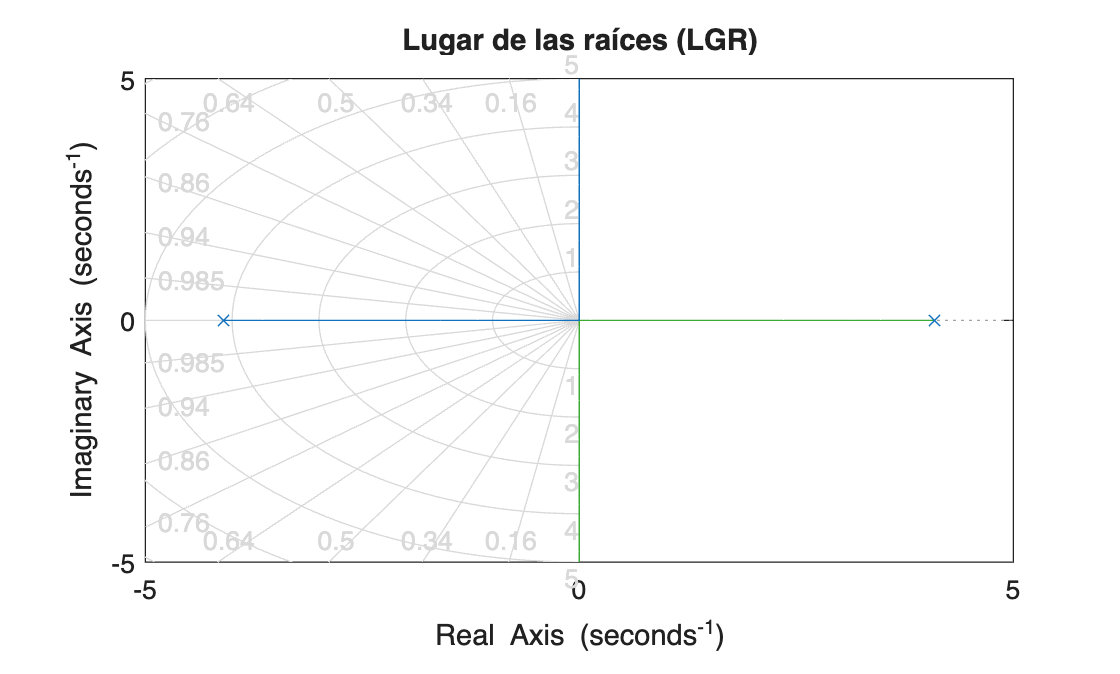


%% 1. Lugar de las raíces
figure;
rlocus(G);
title('Lugar de las raíces (LGR)');
grid on;


% Mostrar polos
poles = pole(G);
disp('Polos del sistema:');

Polos del sistema:


disp(poles);

   -4.0959
    4.0936




p_estables   = poles(real(poles)<0);
p_inestables = poles(real(poles)>0);

fprintf('Polo(s) estable(s): %s\n', mat2str(p_estables));

Polo(s) estable(s): -4.09587457119826


fprintf('Polo(s) inestable(s): %s\n', mat2str(p_inestables));

Polo(s) inestable(s): 4.09361290453159


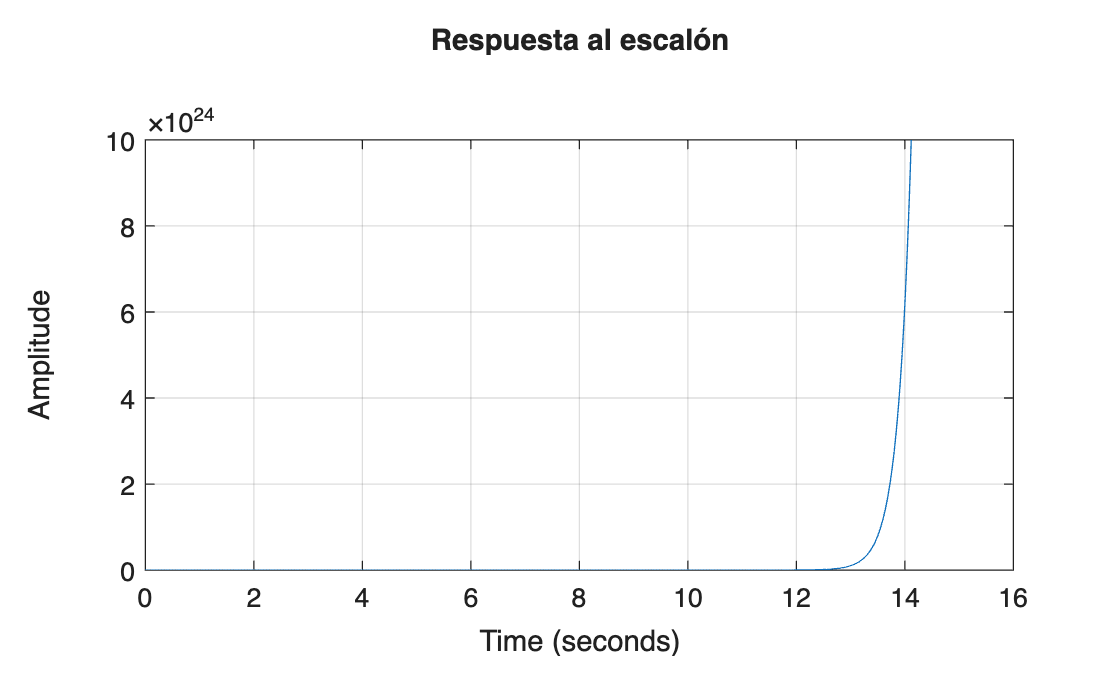


%% 2. Respuestas del sistema
% Respuesta al escalón
figure;
step(G);
title('Respuesta al escalón');
grid on;

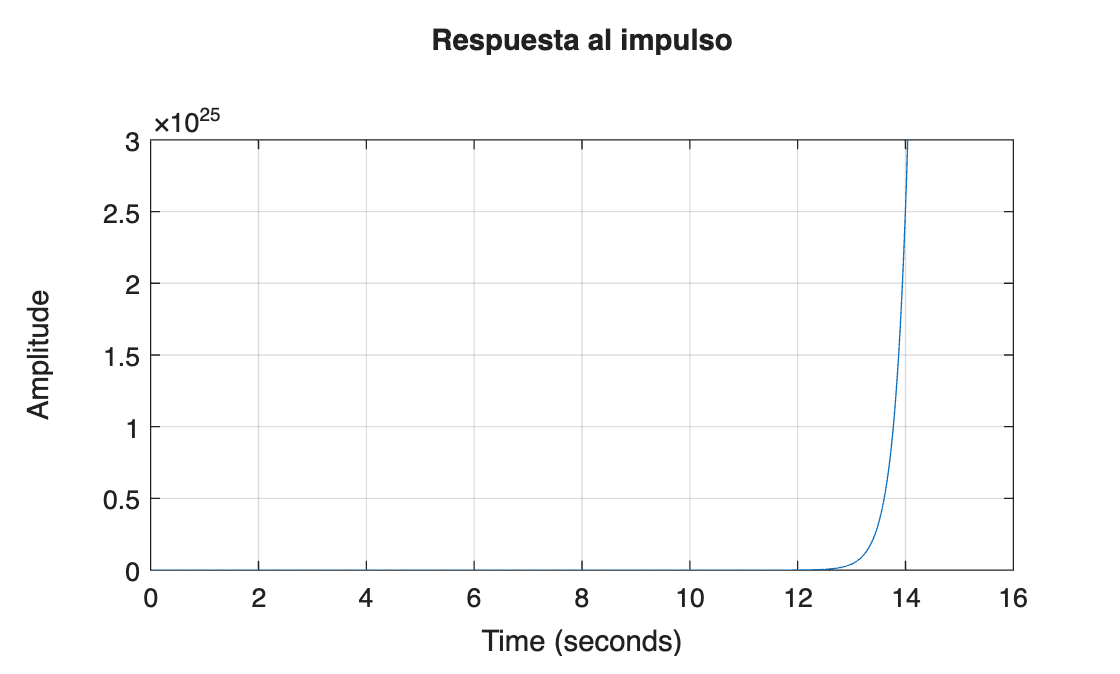


% Respuesta al impulso
figure;
impulse(G);
title('Respuesta al impulso');
grid on;

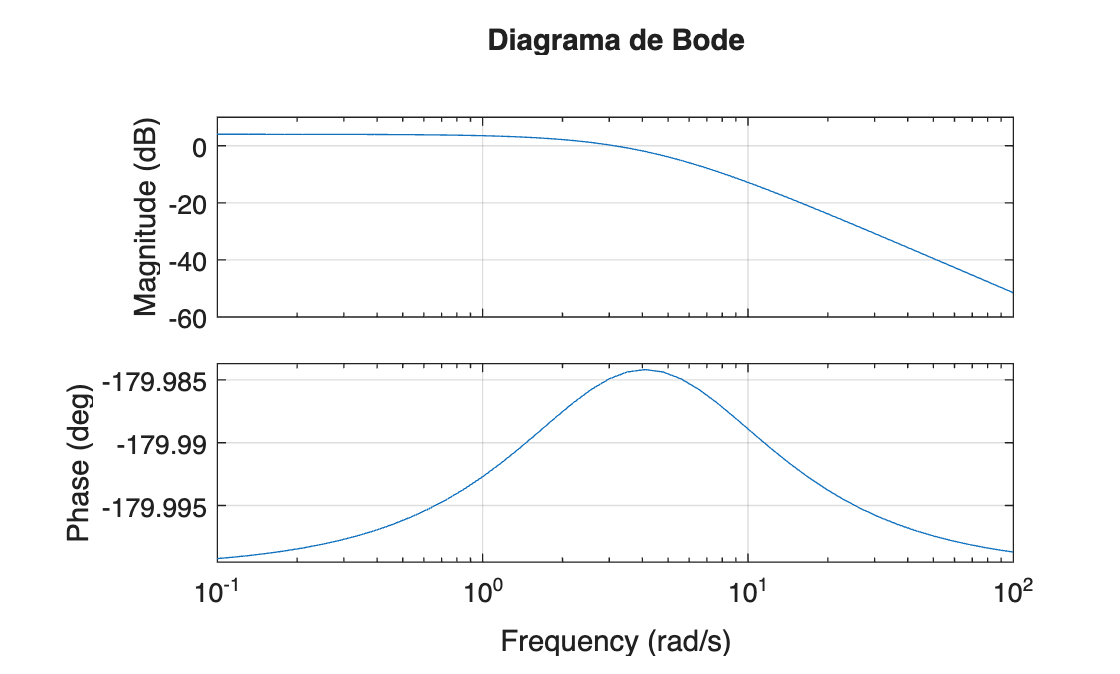


% Diagrama de Bode
figure;
bode(G);
title('Diagrama de Bode');
grid on;